clear
clc
%%%%%% Assumption
% T_upper = T_lower = W/2

%%%%%% COMMON VALUES
%%% Environment
rho_0 = 1.225;    % kg/m^3
T_0 = 288.2;      % K
P_0 = 101325;     % pa
gamma = 1.4;
R_0 = 287.05;
g = 9.8067;       % m/s^2
T_trans = 272.15; % K to °C
%%% Aero team
MTOW = 3491;   % kg     % max take off weight
Wpay = 800;    % kg     % Weight of the payload
Nb = 3;
R = 5.2992;    % m
c = 0.265;     % m      % chord length
Cd0 = 0.01;
omega = 41.5153;        % rotational speed
f = 3.4177;             % equivalent wetted area
CDf = 1;                % drag coefficient based on this reference area
Sref = 1;      % m^2    % reference area
t_c = 0.08;                % thickness ratio
M_dd = 0.86;            % drag divergence Mach number
sweep = 30;    % degree % sweep angle
kappa_ii = 1.1412;       % induce factor
kappa_02 = 4;           % profile factor (mu^2 term)
kappa_04 = 5/8;         % profile factor (mu^4 term)
kappa_int = 1.16;       % interference factor
%%% struc team

%%% syst team
Ne = 2;      % number of engines
Paux = 1;    % power needed (the on board equipments)
SFC = 8.57*10^-8;     % kg/(W*s)
Wf = 300;      % initial fuel weight
Ptotal = 1.5*10^6;  % total power provided by engines
kappa_trans = 1; % transmission factor
%%% Initial calc
GTOW = (MTOW - Wpay) * g;   % N    % gross take off weight(no payload)
MTOW = MTOW * g;            % N
Wpay = Wpay * g;            % N
Wf = Wf * g;                % N
A = pi * R^2;               % m^2  % rotor area
sigema = Nb * c / (pi * R);        % solidity
T_0 = T_0 - T_trans;        % °C

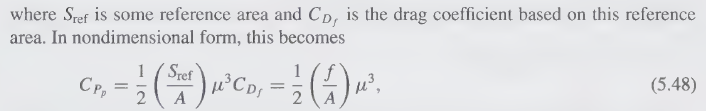

%%%%%% h in feet, T in °C, others in SI units
%%%%%% G indicates no payload, M indicates max payload, V_forward indicates
%%%%%% forward flight speed of aircraft in m/s

%%%%%% max ceiling
h = 0;
V_forward = 0:0.1:90;
mu = V_forward ./ (omega * R);

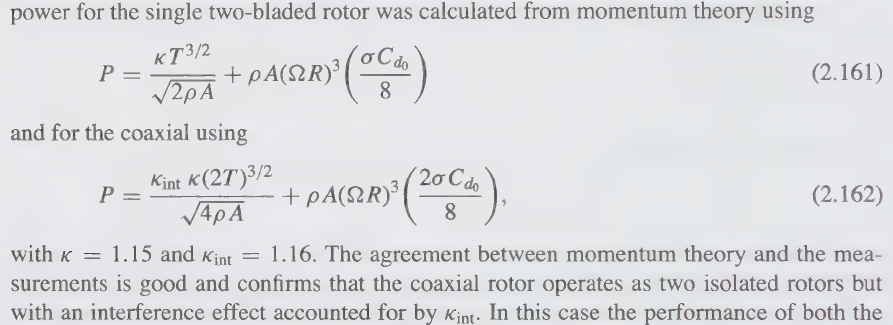

Pi = kappa * T * v

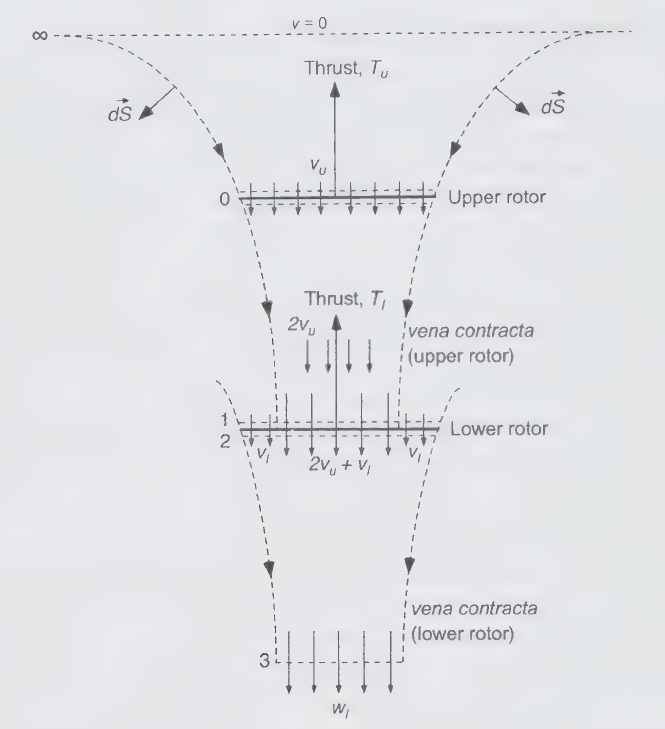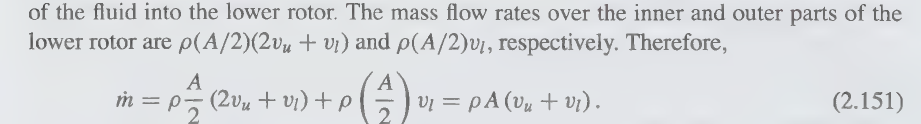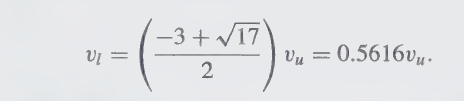

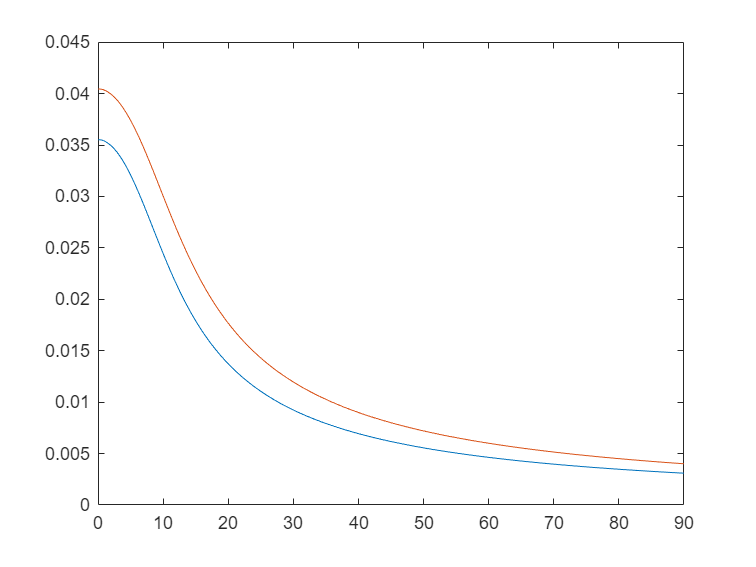

% Pi clac
CT_msl_G = GTOW/(2*rho_0*A*omega^2*R^2);
lambda_msl_initial_G = sqrt(CT_msl_G/2);
lambda_msl_n = lambda_msl_initial_G;
lambda_msl_G = zeros(size(V_forward));
alp = 0;
for j = 1:length(V_forward)
    for i = 1:100
        lambda_msl_n1 = mu(j)*tan(alp) + CT_msl_G / (2*sqrt(mu(j)^2 + lambda_msl_n^2));
        lambda_msl_n = lambda_msl_n1;
    end
    lambda_msl_G(j) = lambda_msl_n1;
end

CT_msl_M = MTOW/(2*rho_0*A*omega^2*R^2);
lambda_msl_initial_M = sqrt(CT_msl_M/2);
lambda_msl_n = lambda_msl_initial_M;
lambda_msl_M = zeros(size(V_forward));
alp = 0;
for j = 1:length(V_forward)
    for i = 1:100
        lambda_msl_n1 = mu(j)*tan(alp) + CT_msl_M / (2*sqrt(mu(j)^2 + lambda_msl_n^2));
        lambda_msl_n = lambda_msl_n1;
    end
    lambda_msl_M(j) = lambda_msl_n1;
end
figure
plot(V_forward,lambda_msl_G)
hold on
plot(V_forward,lambda_msl_M)
hold off

kappa_i = kappa_ii .* cosh(7.5 .* mu.^2);
Pi_msl_G = (kappa_int * GTOW/2 * omega * R * 2) .* lambda_msl_G .* kappa_i;
Pi_msl_M = (kappa_int * MTOW/2 * omega * R * 2) .* lambda_msl_M .* kappa_i;
Cpp_msl = (0.5 * f / A) .* mu.^3;
Pp_msl = Cpp_msl .* (rho_0 * A * omega^3 * R^3);

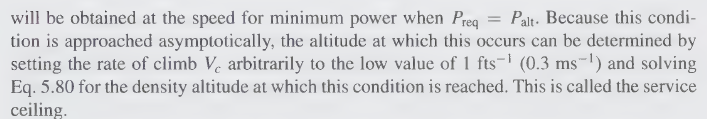

Pc_msl_G = 0.3 * GTOW *ones(size(V_forward));
Pc_msl_M = 0.3 * MTOW *ones(size(V_forward));
Paux_msl = Paux *ones(size(V_forward));

% Po calc
Po_msl = zeros(size(V_forward));
Cpo_pure = sigema * Cd0 .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) ./ 8;

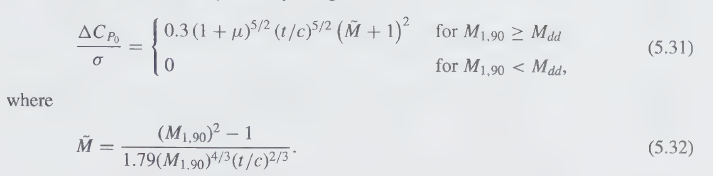

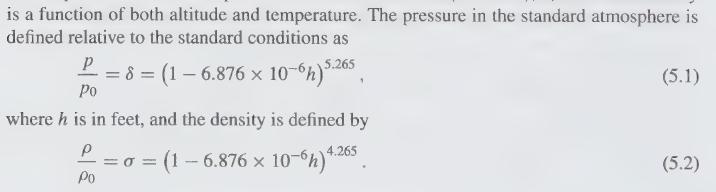

h_M = h;
M_19 = (omega * R + V_forward) ./ sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
M_hat = (M_19.^2 - 1) ./ (1.79 .* M_19.^(4/3) .* t_c^(2/3));
M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
delta_Cpo = zeros(size(V_forward));
for i = 1:length(V_forward)
    if M_19(i) >= M_dd
        delta_Cpo1 = sigema * (0.3 * (1+mu(i))^(5/2) * t_c^(5/2) * (M_hat(i)+1)^2);
    else
        delta_Cpo1 = 0;
    end

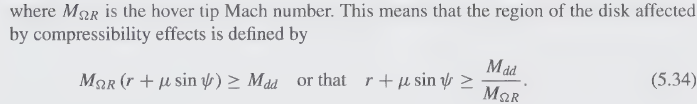

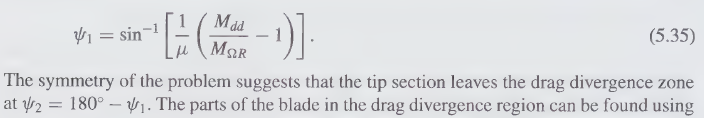

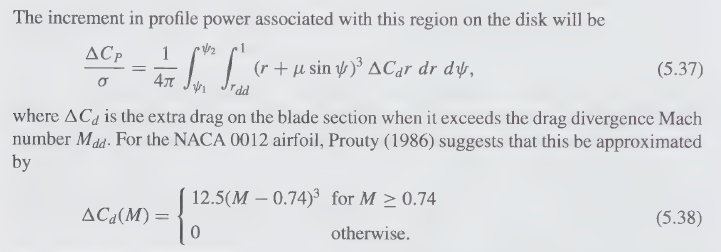

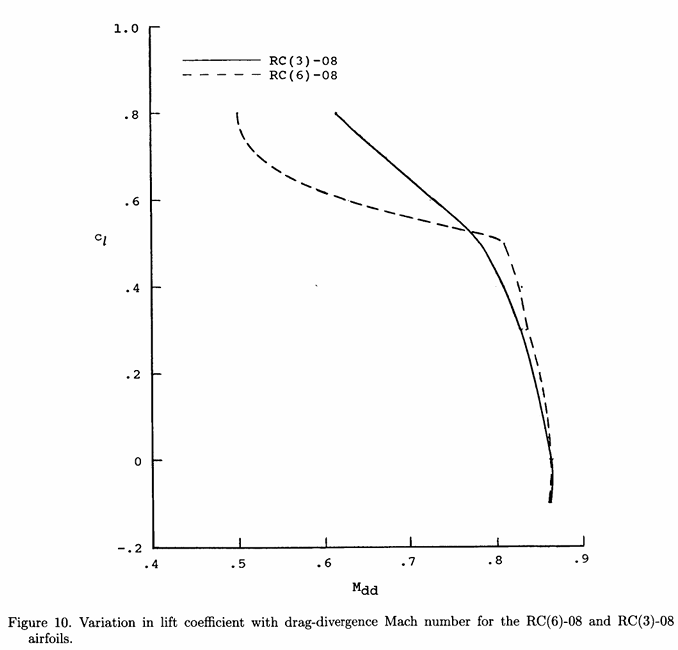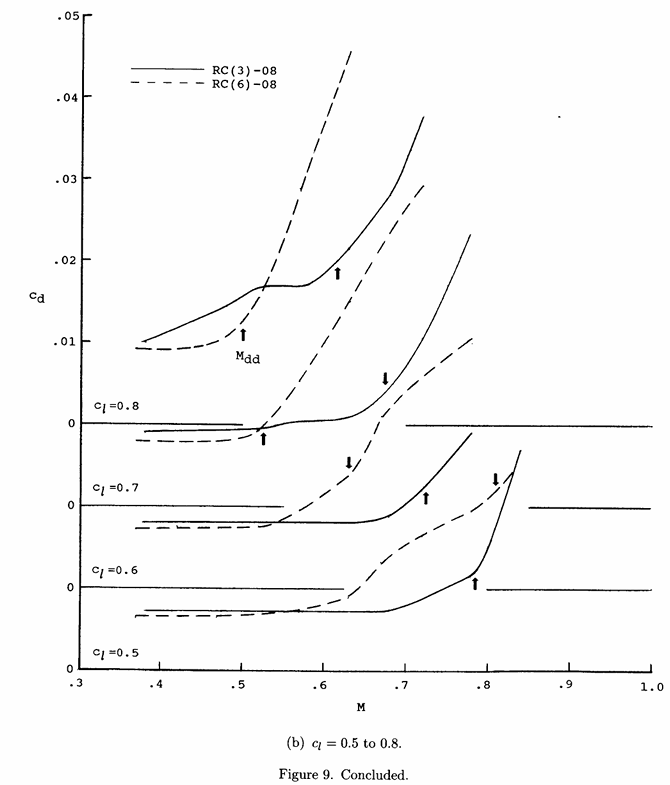

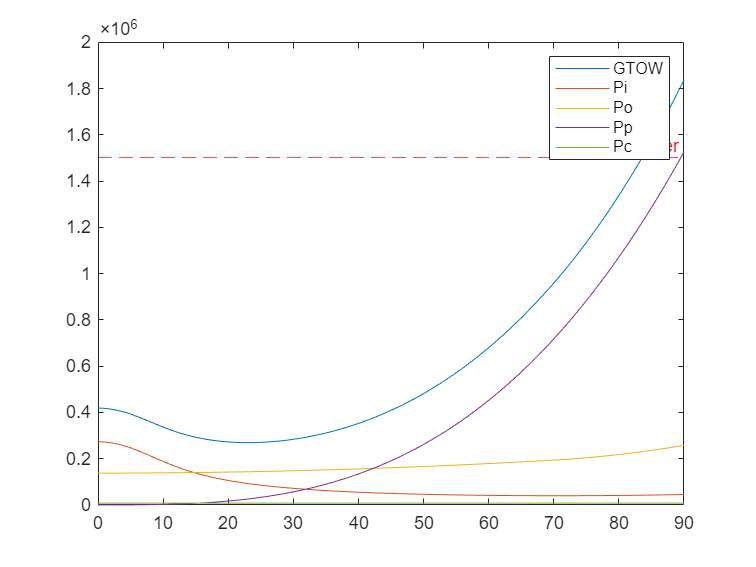

    % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
    M_r = M_hover*(1+mu(i))*cos(sweep);
    if M_r >= M_dd
        psi1 = asin(mu(i)^-1 * (M_dd/M_hover - 1));
        psi2 = 180 - psi1;
        f = @(psi,r) (r + mu(i)*sin(psi))^3 * r * (0.165*M_hover*(r+mu(i)*sin(psi))*cos(sweep)-0.0895)
        delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu(i)*sin(psi),1) / (4 * pi)
    else
        delta_Cpo2 = 0;
    end
    delta_Cpo(i) = delta_Cpo2 + delta_Cpo1;
end
Po_msl = (Cpo_pure+delta_Cpo) .* (2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h_M)^4.265);
P_msl_G = (Pi_msl_G + Po_msl + Pp_msl + Paux_msl) .* kappa_trans;
P_msl_M = (Pi_msl_M + Po_msl + Pp_msl + Paux_msl) .* kappa_trans;
P_msl_ceiling_G = (Pi_msl_G + Po_msl + Pp_msl + Pc_msl_G + Paux_msl) .* kappa_trans;
P_msl_ceiling_M = (Pi_msl_M + Po_msl + Pp_msl + Pc_msl_M + Paux_msl) .* kappa_trans;
figure
plot(V_forward,P_msl_ceiling_G)
hold on
plot(V_forward,Pi_msl_G)
hold on
plot(V_forward,Po_msl)
hold on
plot(V_forward,Pp_msl)
hold on
plot(V_forward,Pc_msl_G)
hold on
yline(Ptotal, '--r', 'Total Power');  % 红色虚线，并加标签
hold on
legend('GTOW','Pi','Po','Pp','Pc')
hold off

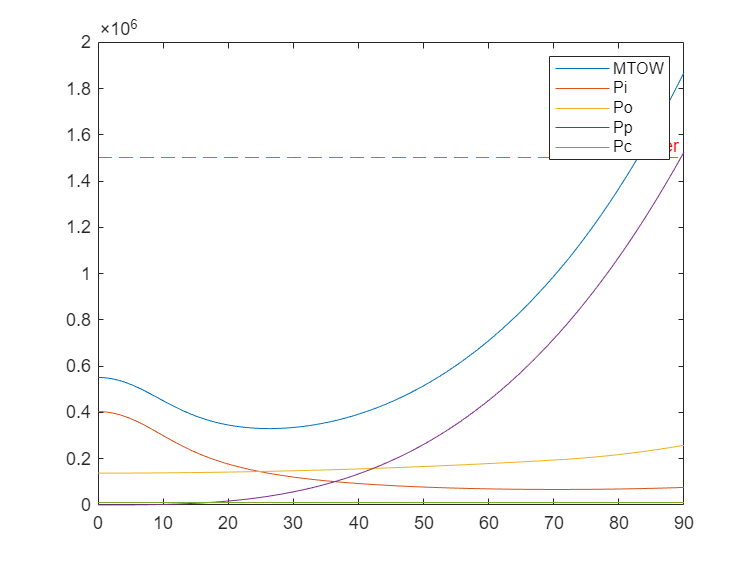

figure
plot(V_forward,P_msl_ceiling_M)
hold on
plot(V_forward,Pi_msl_M)
hold on
plot(V_forward,Po_msl)
hold on
plot(V_forward,Pp_msl)
hold on
plot(V_forward,Pc_msl_M)
hold on
yline(Ptotal, '--r', 'Total Power');  % 红色虚线，并加标签
hold on
legend('MTOW','Pi','Po','Pp','Pc')
hold off


% h_GG = zeros(size(V_forward));
% h_MM = zeros(size(V_forward));
% syms h1
% alp = 0;
% delta_Cpo = 0;
% Cp1_factor_pre = 0;
% Cp2_factor_pre = 0;
% for j = 1:length(V_forward)
%     max_iter = 100;
%     while true
%         mu_G = V_forward(j) / (omega * R);
%         CT_G = GTOW/(2*rho_0*(1-6.876*10^-6*h1)^4.265*A*omega^2*R^2);
%         lambda_initial_G = sqrt(CT_G/2);
%         lambda_n = lambda_initial_G;
%         for i = 1:100
%             lambda_n1 = mu_G*tan(alp) + CT_G / (2*sqrt(mu_G^2 + lambda_n^2));
%             lambda_n = lambda_n1;
%         end
%         lambda_G = lambda_n1;
%         kappa_i = kappa_ii * cosh(7.5 * mu_G^2);
%         Pi_G = (kappa_int * GTOW/2 * omega * R * 2) * lambda_G * kappa_i;
%         Cpp_G = (0.5 * f / A) * mu_G^3;
%         Pp_G = Cpp_G * (rho_0*(1-6.876*10^-6*h1)^4.265 * A * omega^3 * R^3);
%         Pc_G = 0.3 * GTOW;
%         Paux_G = Paux_msl;
%         Cpo_pure = sigema * Cd0 * (1 + kappa_02*mu_G^2 + kappa_04*mu_G^4) / 8;
%         Po_G = (Cpo_pure+delta_Cpo) * 2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h1)^4.265;
%         eqn = kappa_trans * (Pi_G + Po_G + Pp_G + Pc_G + Paux_G) == Ptotal;
%         h_GG(j) = vpasolve(eqn,h1);
%         h_M = h_GG(j);
%         M_19 = (omega * R + V_forward(j)) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
%         M_hat = (M_19^2 - 1) / (1.79 * M_19^(4/3) * t_c^(2/3));
%         M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
%         if M_19 >= M_dd
%             delta_Cpo1 = sigema * (0.3 * (1+mu_G)^(5/2) * t_c^(5/2) * (M_hat+1)^2);
%             Cp1_factor = 1;
%         else
%             delta_Cpo1 = 0;
%             Cp1_factor = 0;
%         end
%         % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
%         M_r = M_hover*(1+mu_G)*cos(sweep);
%         if M_r >= M_dd
%             psi1 = asin(mu_G^-1 * (M_dd/M_hover - 1));
%             psi2 = 180 - psi1;
%             f = @(psi,r) (r + mu_G*sin(psi))^3 * r * (0.165*M_hover*(r+mu_G*sin(psi))*cos(sweep)-0.0895)
%             delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu_G*sin(psi),1) / (4 * pi)
%             Cp2_factor = 1;
%         else
%             delta_Cpo2 = 0;
%             Cp2_factor = 0;
%         end
% 
%         if isequal(Cp1_factor,Cp1_factor_pre) && isequal(Cp2_factor, Cp2_factor_pre)
%             disp("Parameters unchanged. Exiting loop.");
%             break;
%         end
% 
%         delta_Cpo = delta_Cpo1 + delta_Cpo2;
%         Cp1_factor_pre = Cp1_factor;
%         Cp2_factor_pre = Cp2_factor;
%     end
% end
% 
% syms h2
% alp = 0;
% delta_Cpo = 0;
% Cp1_factor_pre = 0;
% Cp2_factor_pre = 0;
% for j = 1:length(V_forward)
%     max_iter = 100;
%     while ture
%         mu_M = V_forward(j) / (omega * R);
%         CT_M = MTOW/(2*rho_0*(1-6.876*10^-6*h2)^4.265*A*omega^2*R^2);
%         lambda_initial_G = sqrt(CT_M/2);
%         lambda_n = lambda_initial_G;
%         for i = 1:100
%             lambda_n1 = mu_M*tan(alp) + CT_M / (2*sqrt(mu_M^2 + lambda_n^2));
%             lambda_n = lambda_n1;
%         end
%         lambda_M = lambda_n1;
%         kappa_i = kappa_ii * cosh(7.5 * mu_M^2);
%         Pi_M = (kappa_int * GTOW/2 * omega * R * 2) * lambda_M * kappa_i;
%         Cpp_M = (0.5 * f / A) * mu_M^3;
%         Pp_M = Cpp_M * (rho_0*(1-6.876*10^-6*h2)^4.265 * A * omega^3 * R^3);
%         Pc_M = 0.3 * MTOW;
%         Paux_M = Paux_msl;
%         Cpo_pure = sigema * Cd0 * (1 + kappa_02*mu_M^2 + kappa_04*mu_M^4) / 8;
%         Po_M = (Cpo_pure+delta_Cpo) * 2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h2)^4.265;
%         eqn = kappa_trans * (Pi_M + Po_M + Pp_M + Pc_M + Paux_M) == Ptotal;
%         h_MM(j) = vpasolve(eqn,h2);
%         h_M = h_MM(j);
%         M_19 = (omega * R + V_forward(j)) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
%         M_hat = (M_19^2 - 1) / (1.79 * M_19^(4/3) * t_c^(2/3));
%         M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
%         if M_19 >= M_dd
%             delta_Cpo1 = sigema * (0.3 * (1+mu_M)^(5/2) * t_c^(5/2) * (M_hat+1)^2);
%             Cp1_factor = 1;
%         else
%             delta_Cpo1 = 0;
%             Cp1_factor = 0;
%         end
%         % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
%         M_r = M_hover*(1+mu_M)*cos(sweep);
%         if M_r >= M_dd
%             psi1 = asin(mu_M^-1 * (M_dd/M_hover - 1));
%             psi2 = 180 - psi1;
%             f = @(psi,r) (r + mu_M*sin(psi))^3 * r * (0.165*M_hover*(r+mu_M*sin(psi))*cos(sweep)-0.0895)
%             delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu_M*sin(psi),1) / (4 * pi)
%             Cp2_factor = 1;
%         else
%             delta_Cpo2 = 0;
%             Cp2_factor = 0;
%         end
% 
%         if isequal(Cp1_factor,Cp1_factor_pre) && isequal(Cp2_factor, Cp2_factor_pre)
%             disp("Parameters unchanged. Exiting loop.");
%             break;
%         end
% 
%         delta_Cpo = delta_Cpo1 + delta_Cpo2;
%         Cp1_factor_pre = Cp1_factor;
%         Cp2_factor_pre = Cp2_factor;
%     end
% end
% figure
% plot(V_forward,h_GG)
% hold on
% plot(V_forward,h_M)
% hold off

%%%%%% Max range&endurance

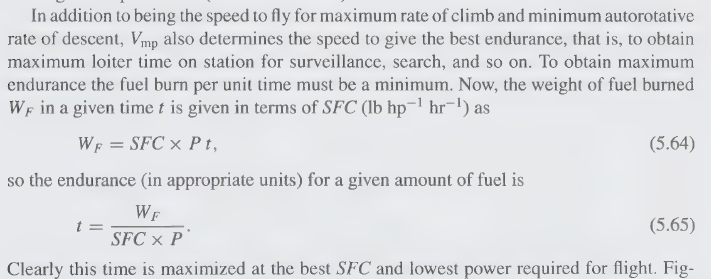

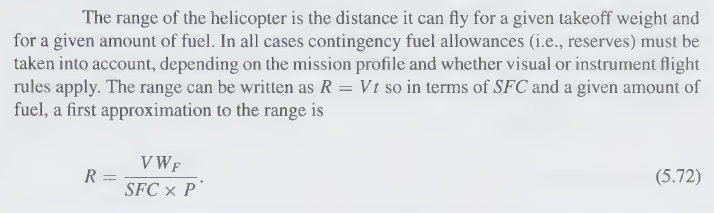

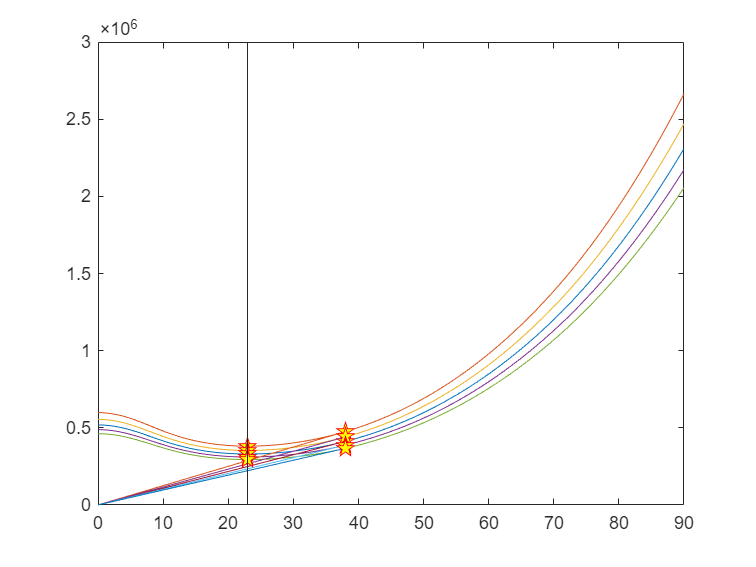

% h in feets
h_diff = 500;
h_cruise = 1500;
h_1 = h_cruise + 2 * h_diff;
h_2 = h_cruise + h_diff;
h_3 = h_cruise - h_diff;
h_4 = h_cruise - 2 * h_diff;
P_cruise_G = P_msl_G .* ((1-6.876*10^-6*h_cruise)^5.265 / ((15-0.001981*h_cruise)/T_0));
P_1_G = P_msl_G .* ((1-6.876*10^-6*h_1)^5.265 / ((15-0.001981*h_1)/T_0));
P_2_G = P_msl_G .* ((1-6.876*10^-6*h_2)^5.265 / ((15-0.001981*h_2)/T_0));
P_3_G = P_msl_G .* ((1-6.876*10^-6*h_3)^5.265 / ((15-0.001981*h_3)/T_0));
P_4_G = P_msl_G .* ((1-6.876*10^-6*h_4)^5.265 / ((15-0.001981*h_4)/T_0));
[Pmp_cruise, idx_cruise] = min(P_cruise_G);
[Pmp_1, idx_1] = min(P_1_G);
[Pmp_2, idx_2] = min(P_2_G);
[Pmp_3, idx_3] = min(P_3_G);
[Pmp_4, idx_4] = min(P_4_G);
hmp_G = [h_1,h_2,h_cruise,h_3,h_4];
Vmp_G = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_cruise),V_forward(idx_3),V_forward(idx_4)];
Pmp_G = [Pmp_1,Pmp_2,Pmp_cruise,Pmp_3,Pmp_4];
endurance_G = (Wf./g) ./ (SFC .* Pmp_G);
k_cruise = P_cruise_G ./ V_forward;
k_1 = P_1_G ./ V_forward;
k_2 = P_2_G ./ V_forward;
k_3 = P_3_G ./ V_forward;
k_4 = P_4_G ./ V_forward;
[~, idx_range_cruise] = min(k_cruise);
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
hrange_G = [h_1,h_2,h_cruise,h_3,h_4];
Vrange_G = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_cruise),V_forward(idx_range_3),V_forward(idx_range_4)];
Prange_G = [P_1_G(idx_range_1),P_2_G(idx_range_2),P_cruise_G(idx_range_cruise),P_3_G(idx_range_3),P_4_G(idx_range_4)];
range_G = (Vrange_G .* (Wf./g)) ./ (SFC .* Prange_G);
figure
plot(V_forward,P_cruise_G)
hold on
plot(V_forward,P_1_G)
hold on
plot(V_forward,P_2_G)
hold on
plot(V_forward,P_3_G)
hold on
plot(V_forward,P_4_G)
hold on
plot(Vmp_G,Pmp_G)
hold on
plot([0,V_forward(idx_range_cruise)], [0,P_cruise_G(idx_range_cruise)]);
hold on
plot(V_forward(idx_range_cruise), P_cruise_G(idx_range_cruise), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_G(idx_range_1)]);
hold on
plot(V_forward(idx_range_1), P_1_G(idx_range_1), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_G(idx_range_2)]);
hold on
plot(V_forward(idx_range_2), P_2_G(idx_range_2), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_G(idx_range_3)]);
hold on
plot(V_forward(idx_range_3), P_3_G(idx_range_3), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_G(idx_range_4)]);
hold on
plot(V_forward(idx_range_4), P_4_G(idx_range_4), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(1),'-')
hold on
plot(Vmp_G(1), Pmp_G(1), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(2),'-')
hold on
plot(Vmp_G(2), Pmp_G(2), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(3),'-')
hold on
plot(Vmp_G(3), Pmp_G(3), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(4),'-')
hold on
plot(Vmp_G(4), Pmp_G(4), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_G(5),'-')
hold on
plot(Vmp_G(5), Pmp_G(5), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold off

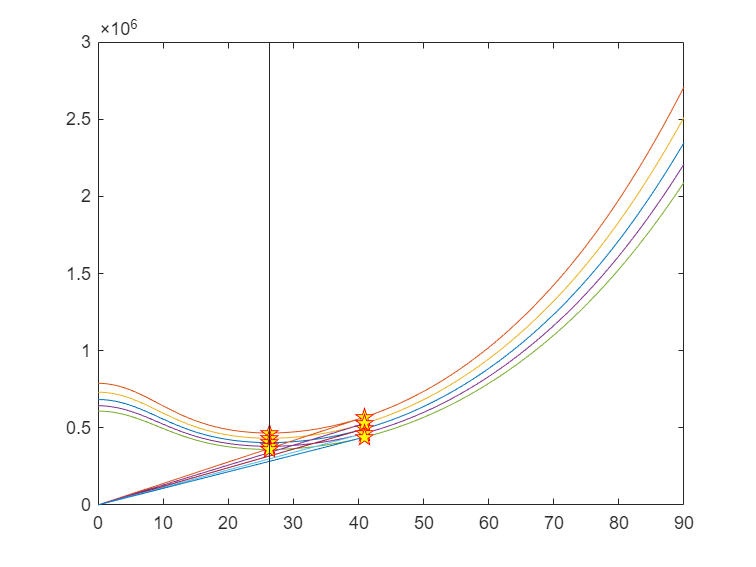

P_cruise_M = P_msl_M .* ((1-6.876*10^-6*h_cruise)^5.265 / ((15-0.001981*h_cruise)/T_0));
P_1_M = P_msl_M .* ((1-6.876*10^-6*h_1)^5.265 / ((15-0.001981*h_1)/T_0));
P_2_M = P_msl_M .* ((1-6.876*10^-6*h_2)^5.265 / ((15-0.001981*h_2)/T_0));
P_3_M = P_msl_M .* ((1-6.876*10^-6*h_3)^5.265 / ((15-0.001981*h_3)/T_0));
P_4_M = P_msl_M .* ((1-6.876*10^-6*h_4)^5.265 / ((15-0.001981*h_4)/T_0));
[Pmp_cruise, idx_cruise] = min(P_cruise_M);
[Pmp_1, idx_1] = min(P_1_M);
[Pmp_2, idx_2] = min(P_2_M);
[Pmp_3, idx_3] = min(P_3_M);
[Pmp_4, idx_4] = min(P_4_M);
hmp_M = [h_1,h_2,h_cruise,h_3,h_4];
Vmp_M = [V_forward(idx_1),V_forward(idx_2),V_forward(idx_cruise),V_forward(idx_3),V_forward(idx_4)];
Pmp_M = [Pmp_1,Pmp_2,Pmp_cruise,Pmp_3,Pmp_4];
endurance_M = (Wf./g) ./ (SFC .* Pmp_M);
k_cruise = P_cruise_M ./ V_forward;
k_1 = P_1_M ./ V_forward;
k_2 = P_2_M ./ V_forward;
k_3 = P_3_M ./ V_forward;
k_4 = P_4_M ./ V_forward;
[~, idx_range_cruise] = min(k_cruise);
[~, idx_range_1] = min(k_1);
[~, idx_range_2] = min(k_2);
[~, idx_range_3] = min(k_3);
[~, idx_range_4] = min(k_4);
hrange = [h_1,h_2,h_cruise,h_3,h_4];
Vrange_M = [V_forward(idx_range_1),V_forward(idx_range_2),V_forward(idx_range_cruise),V_forward(idx_range_3),V_forward(idx_range_4)];
Prange_M = [P_1_M(idx_range_1),P_2_M(idx_range_2),P_cruise_M(idx_range_cruise),P_3_M(idx_range_3),P_4_M(idx_range_4)];
range_M = (Vrange_M .* (Wf./g)) ./ (SFC .* Prange_M);
figure
plot(V_forward,P_cruise_M)
hold on
plot(V_forward,P_1_M)
hold on
plot(V_forward,P_2_M)
hold on
plot(V_forward,P_3_M)
hold on
plot(V_forward,P_4_M)
hold on
plot(Vmp_M,Pmp_M)
hold on
plot([0,V_forward(idx_range_cruise)], [0,P_cruise_M(idx_range_cruise)]);
hold on
plot(V_forward(idx_range_cruise), P_cruise_M(idx_range_cruise), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_1)], [0,P_1_M(idx_range_1)]);
hold on
plot(V_forward(idx_range_1), P_1_M(idx_range_1), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_2)], [0,P_2_M(idx_range_2)]);
hold on
plot(V_forward(idx_range_2), P_2_M(idx_range_2), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_3)], [0,P_3_M(idx_range_3)]);
hold on
plot(V_forward(idx_range_3), P_3_M(idx_range_3), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
plot([0,V_forward(idx_range_4)], [0,P_4_M(idx_range_4)]);
hold on
plot(V_forward(idx_range_4), P_4_M(idx_range_4), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(1),'-')
hold on
plot(Vmp_M(1), Pmp_M(1), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(2),'-')
hold on
plot(Vmp_M(2), Pmp_M(2), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(3),'-')
hold on
plot(Vmp_M(3), Pmp_M(3), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(4),'-')
hold on
plot(Vmp_M(4), Pmp_M(4), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold on
xline(Vmp_M(5),'-')
hold on
plot(Vmp_M(5), Pmp_M(5), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'y');
hold off

Trange = table(hrange',Vrange_M',Prange_M',range_M',Vrange_G',Prange_G',range_G');
Tendurance = table(hmp_G',Vmp_M',Pmp_M',endurance_M',Vmp_G',Pmp_G',endurance_G');
disp(Trange)

    Var1    Var2       Var3          Var4       Var5       Var6          Var7   
    ____    ____    __________    __________    ____    __________    __________

    2500    40.9    5.6909e+05    2.5158e+05     38     4.7561e+05    2.7969e+05
    2000    40.9    5.2764e+05    2.7135e+05     38     4.4096e+05    3.0166e+05
    1500    40.9    4.9314e+05    2.9033e+05     38     4.1213e+05    3.2277e+05
    1000    40.9    4.6402e+05    3.0855e+05     38     3.8779e+05    3.4302e+05
     500    40.9    4.3913e+05    3.2604e+05     38     3.6699e+05    3.6247e+05



disp(Tendurance)

    Var1    Var2       Var3        Var4     Var5       Var6        Var7 
    ____    ____    __________    ______    ____    __________    ______

    2500    26.3    4.6614e+05    7509.7     23     3.8098e+05    9188.4
    2000    26.3    4.3219e+05    8099.7     23     3.5322e+05    9910.4
    1500    26.3    4.0393e+05    8666.3     23     3.3013e+05     10604
    1000    26.3    3.8008e+05    9210.2     23     3.1063e+05     11269
     500    26.3    3.5969e+05    9732.3     23     2.9397e+05     11908



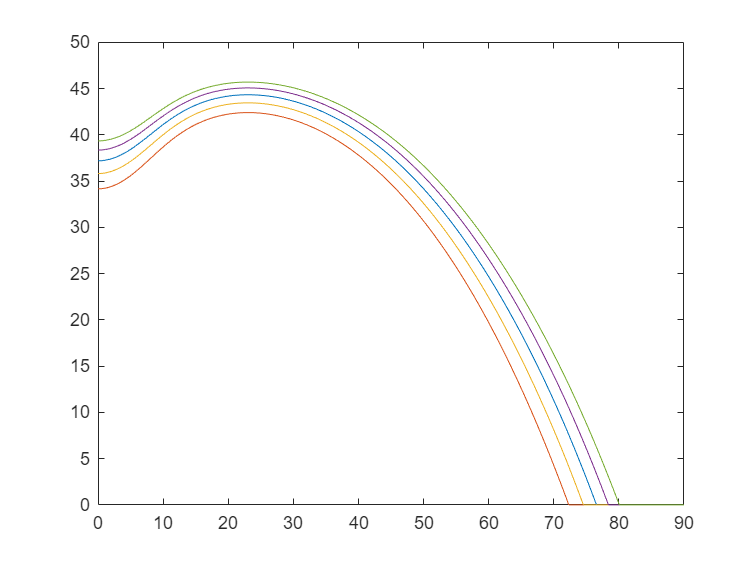

%%%%%% Climb performance (V_forward indicates climb speed, Vc indicates rate of climb )
Vc_1_M = (Ptotal - P_1_M) ./ MTOW;
Vc_2_M = (Ptotal - P_2_M) / MTOW;
Vc_cruise_M = (Ptotal - P_cruise_M) / MTOW;
Vc_3_M = (Ptotal - P_3_M) / MTOW;
Vc_4_M = (Ptotal - P_4_M) / MTOW;
Vc_1_G = (Ptotal - P_1_G) / GTOW;
Vc_2_G = (Ptotal - P_2_G) / GTOW;
Vc_cruise_G = (Ptotal - P_cruise_G) / GTOW;
Vc_3_G = (Ptotal - P_3_G) / GTOW;
Vc_4_G = (Ptotal - P_4_G) / GTOW;
Vc_1_G(Vc_1_G < 0) = 0;
Vc_2_G(Vc_2_G < 0) = 0;
Vc_cruise_G(Vc_cruise_G < 0) = 0;
Vc_3_G(Vc_3_G < 0) = 0;
Vc_4_G(Vc_4_G < 0) = 0;
Vc_1_M(Vc_1_M < 0) = 0;
Vc_2_M(Vc_2_M < 0) = 0;
Vc_cruise_M(Vc_cruise_M < 0) = 0;
Vc_3_M(Vc_3_M < 0) = 0;
Vc_4_M(Vc_4_M < 0) = 0;
figure
plot(V_forward,Vc_cruise_G);
hold on
plot(V_forward,Vc_1_G);
hold on
plot(V_forward,Vc_2_G);
hold on
plot(V_forward,Vc_3_G);
hold on
plot(V_forward,Vc_4_G);
hold off

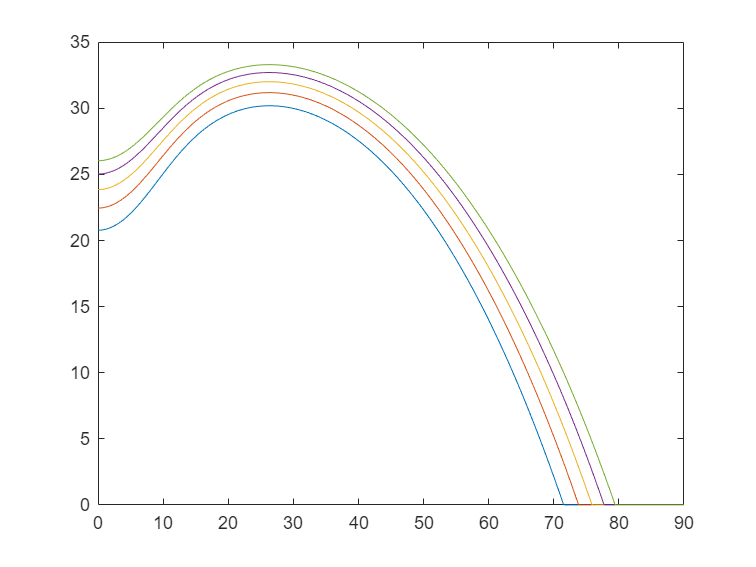

figure
plot(V_forward,Vc_1_M);
hold on
plot(V_forward,Vc_2_M);
hold on
plot(V_forward,Vc_cruise_M);
hold on
plot(V_forward,Vc_3_M);
hold on
plot(V_forward,Vc_4_M);
hold off

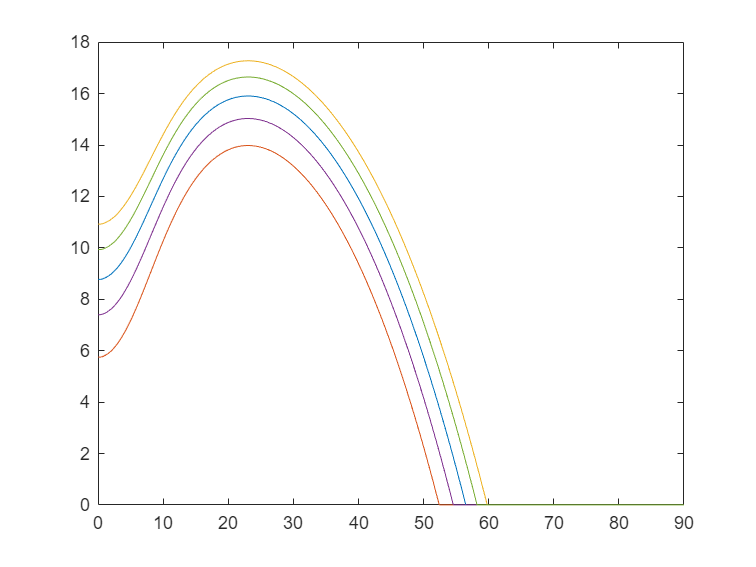

%%%%%% Climb performance OEI
Vc_1_M_OEI = (Ptotal/2 - P_1_M) ./ MTOW;
Vc_2_M_OEI = (Ptotal/2 - P_2_M) / MTOW;
Vc_cruise_M_OEI = (Ptotal/2 - P_cruise_M) / MTOW;
Vc_3_M_OEI = (Ptotal/2 - P_3_M) / MTOW;
Vc_4_M_OEI = (Ptotal/2 - P_4_M) / MTOW;
Vc_1_G_OEI = (Ptotal/2 - P_1_G) / GTOW;
Vc_2_G_OEI = (Ptotal/2 - P_2_G) / GTOW;
Vc_cruise_G_OEI = (Ptotal/2 - P_cruise_G) / GTOW;
Vc_3_G_OEI = (Ptotal/2 - P_3_G) / GTOW;
Vc_4_G_OEI = (Ptotal/2 - P_4_G) / GTOW;
Vc_1_G_OEI(Vc_1_G_OEI < 0) = 0;
Vc_2_G_OEI(Vc_2_G_OEI < 0) = 0;
Vc_cruise_G_OEI(Vc_cruise_G_OEI < 0) = 0;
Vc_3_G_OEI(Vc_3_G_OEI < 0) = 0;
Vc_4_G_OEI(Vc_4_G_OEI < 0) = 0;
Vc_1_M_OEI(Vc_1_M_OEI < 0) = 0;
Vc_2_M_OEI(Vc_2_M_OEI < 0) = 0;
Vc_cruise_M_OEI(Vc_cruise_M_OEI < 0) = 0;
Vc_3_M_OEI(Vc_3_M_OEI < 0) = 0;
Vc_4_M_OEI(Vc_4_M_OEI < 0) = 0;
figure
plot(V_forward,Vc_cruise_G_OEI);
hold on
plot(V_forward,Vc_1_G_OEI);
hold on
plot(V_forward,Vc_4_G_OEI);
hold on
plot(V_forward,Vc_2_G_OEI);
hold on
plot(V_forward,Vc_3_G_OEI);
hold off

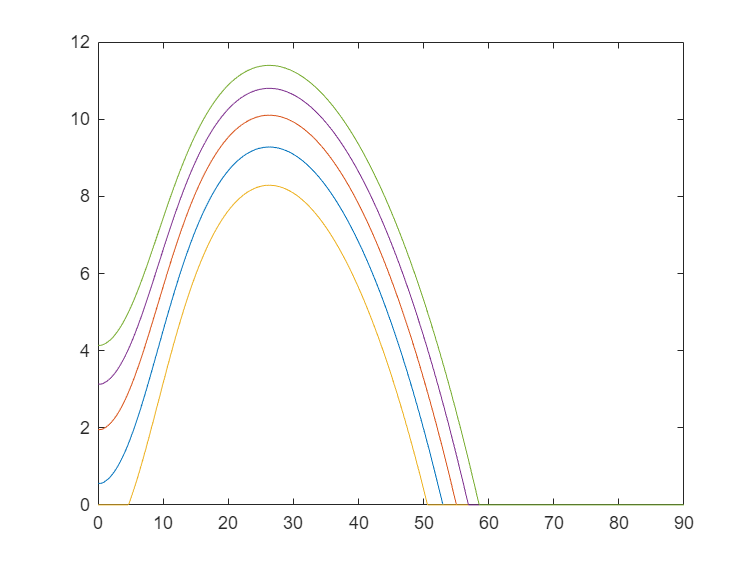

figure
plot(V_forward,Vc_2_M_OEI);
hold on
plot(V_forward,Vc_cruise_M_OEI);
hold on
plot(V_forward,Vc_1_M_OEI);
hold on
plot(V_forward,Vc_3_M_OEI);
hold on
plot(V_forward,Vc_4_M_OEI);
hold off

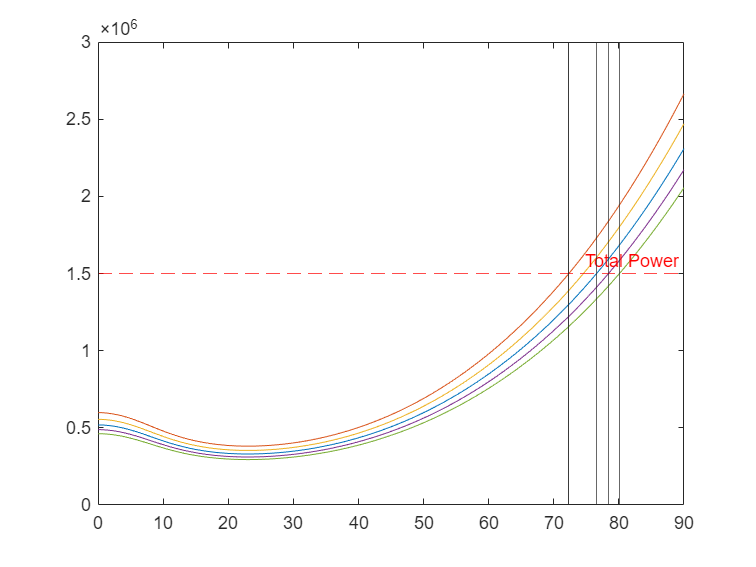

%%%%%% max forward speed
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal));
[~,idx_Vmax_2_G] = min(abs(P_1_G - Ptotal));
[~,idx_Vmax_cruise_G] = min(abs(P_cruise_G - Ptotal));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal));
[~,idx_Vmax_cruise_M] = min(abs(P_cruise_M - Ptotal));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal));
figure
plot(V_forward,P_cruise_G)
hold on
plot(V_forward,P_1_G)
hold on
plot(V_forward,P_2_G)
hold on
plot(V_forward,P_3_G)
hold on
plot(V_forward,P_4_G)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G))
hold on
xline(V_forward(idx_Vmax_2_G))
hold on
xline(V_forward(idx_Vmax_3_G))
hold on
xline(V_forward(idx_Vmax_4_G))
hold on
xline(V_forward(idx_Vmax_cruise_G))
hold off

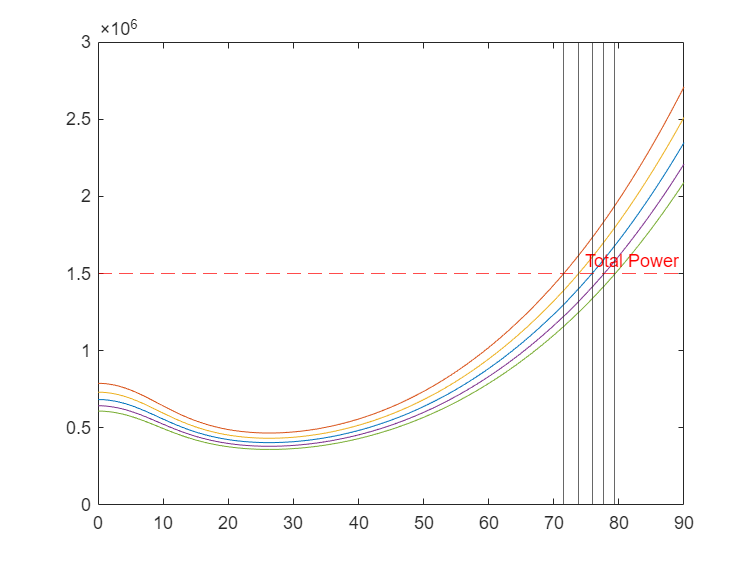

figure
plot(V_forward,P_cruise_M)
hold on
yline(Ptotal, '--r', 'Total Power');
hold on
plot(V_forward,P_1_M)
hold on
plot(V_forward,P_2_M)
hold on
plot(V_forward,P_3_M)
hold on
plot(V_forward,P_4_M)
hold on
xline(V_forward(idx_Vmax_1_M))
hold on
xline(V_forward(idx_Vmax_2_M))
hold on
xline(V_forward(idx_Vmax_3_M))
hold on
xline(V_forward(idx_Vmax_4_M))
hold on
xline(V_forward(idx_Vmax_cruise_M))
hold off

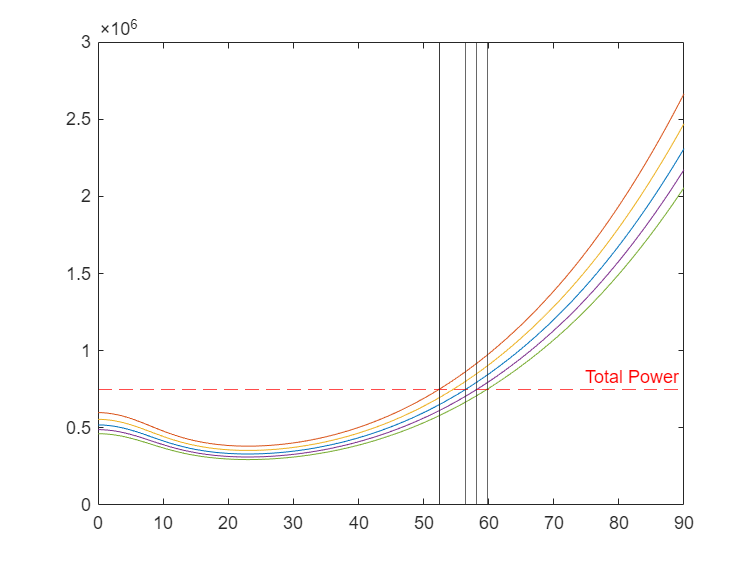

%%%%%% max forward speed (OEI)
Ptotal_OEI = Ptotal/2;
[~,idx_Vmax_1_G] = min(abs(P_1_G - Ptotal_OEI));
[~,idx_Vmax_2_G] = min(abs(P_1_G - Ptotal_OEI));
[~,idx_Vmax_cruise_G] = min(abs(P_cruise_G - Ptotal_OEI));
[~,idx_Vmax_3_G] = min(abs(P_3_G - Ptotal_OEI));
[~,idx_Vmax_4_G] = min(abs(P_4_G - Ptotal_OEI));
[~,idx_Vmax_1_M] = min(abs(P_1_M - Ptotal_OEI));
[~,idx_Vmax_2_M] = min(abs(P_2_M - Ptotal_OEI));
[~,idx_Vmax_cruise_M] = min(abs(P_cruise_M - Ptotal_OEI));
[~,idx_Vmax_3_M] = min(abs(P_3_M - Ptotal_OEI));
[~,idx_Vmax_4_M] = min(abs(P_4_M - Ptotal_OEI));
figure
plot(V_forward,P_cruise_G)
hold on
plot(V_forward,P_1_G)
hold on
plot(V_forward,P_2_G)
hold on
plot(V_forward,P_3_G)
hold on
plot(V_forward,P_4_G)
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_1_G))
hold on
xline(V_forward(idx_Vmax_2_G))
hold on
xline(V_forward(idx_Vmax_3_G))
hold on
xline(V_forward(idx_Vmax_4_G))
hold on
xline(V_forward(idx_Vmax_cruise_G))
hold off

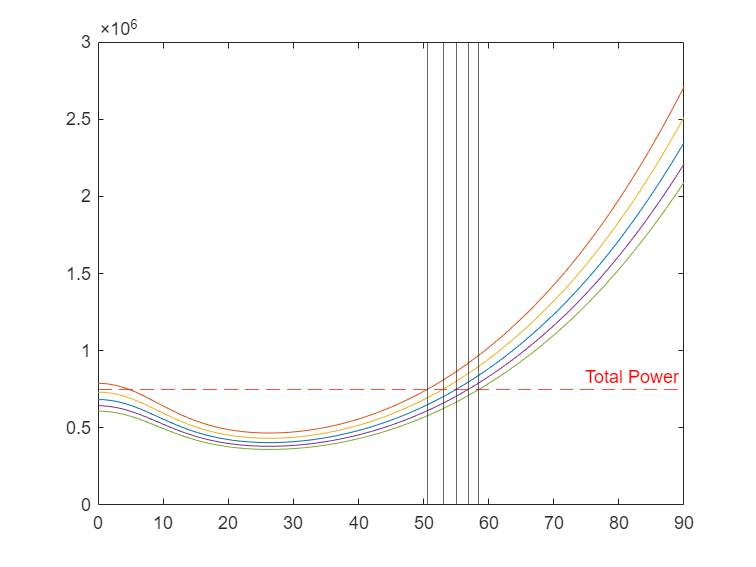

figure
plot(V_forward,P_cruise_M)
hold on
plot(V_forward,P_1_M)
hold on
plot(V_forward,P_2_M)
hold on
plot(V_forward,P_3_M)
hold on
plot(V_forward,P_4_M)
hold on
xline(V_forward(idx_Vmax_1_M))
hold on
xline(V_forward(idx_Vmax_2_M))
hold on
yline(Ptotal_OEI, '--r', 'Total Power');
hold on
xline(V_forward(idx_Vmax_3_M))
hold on
xline(V_forward(idx_Vmax_4_M))
hold on
xline(V_forward(idx_Vmax_cruise_M))
hold off

%%%%%% Range—Payload and Endurance—Payload Relations

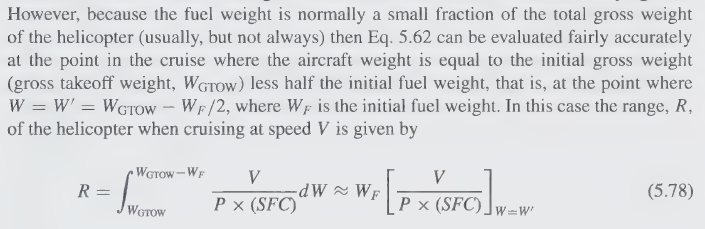

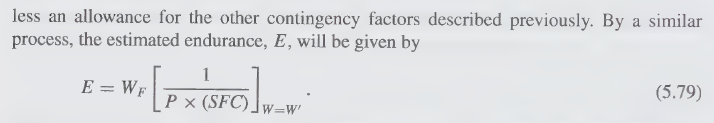

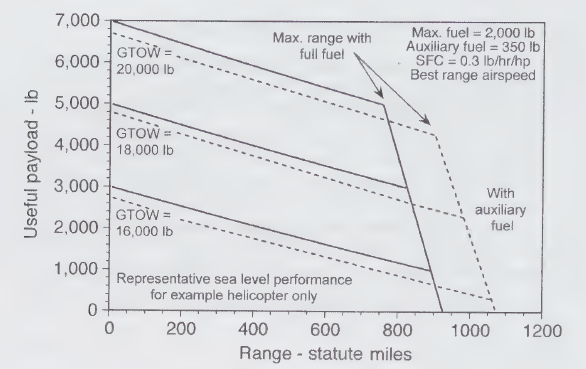

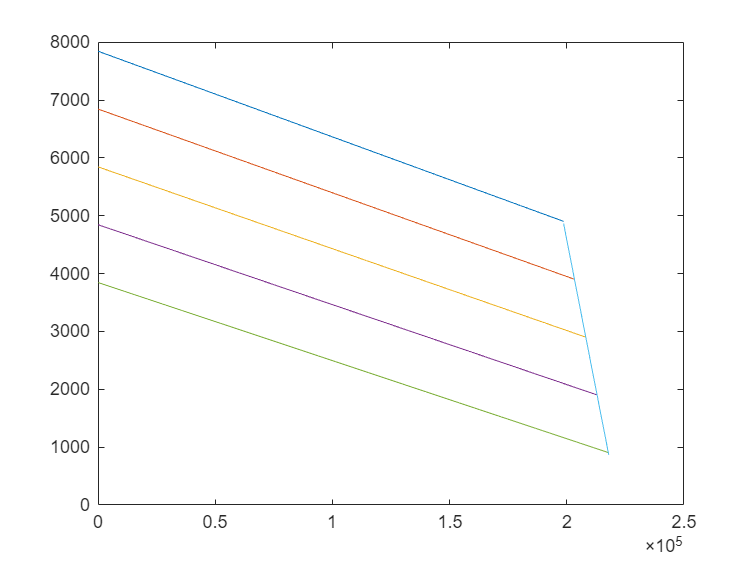

GTOW_diff = 1000; % N
Wf_range = 0:1:Wf;
W_1 = MTOW;
W_2 = W_1 - GTOW_diff;
W_3 = W_2 - GTOW_diff;
W_4 = W_3 - GTOW_diff;
W_5 = W_4 - GTOW_diff;
Wpay_1 = Wpay - Wf_range;
Wpay_2 = Wpay_1 - GTOW_diff;
Wpay_3 = Wpay_2 - GTOW_diff;
Wpay_4 = Wpay_3 - GTOW_diff;
Wpay_5 = Wpay_4 - GTOW_diff;
W = [W_1,W_2,W_3,W_4,W_5];
R_factor = zeros(size(W));
E_factor = zeros(size(W));
for j = 1:length(W)
    h_range = h_cruise;
    mu_range = V_forward ./ (omega * R);
    Pi_range = kappa_int * kappa_i * W(j)^(3/2) / sqrt(4 * rho_0*(1-6.876*10^-6*h_range)^4.265 * A);
    Cpp_range = (0.5 * f / A) .* mu.^3;
    Pp_range = Cpp_range .* (rho_0*(1-6.876*10^-6*h_range)^4.265 * A * omega^3 * R^3);
    Paux_range = Paux;
    % Po calc
    Po_msl = zeros(size(V_forward));
    Cpo_pure = sigema * Cd0 .* (1 + kappa_02.*mu.^2 + kappa_04.*mu.^4) ./ 8;
    h_M = h_range;
    M_19 = (omega * R + V_forward) ./ sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
    M_hat = (M_19.^2 - 1) ./ (1.79 .* M_19.^(4/3) .* t_c^(2/3));
    M_hover = (omega * R) / sqrt(gamma * R_0 * ((15 - 0.001981 * h_M) + T_trans));
    for i = 1:length(V_forward)
        if M_19(i) >= M_dd
            delta_Cpo = sigema * (0.3 * (1+mu(i))^(5/2) * t_c^(5/2) * (M_hat(i)+1)^2);
        else
            delta_Cpo = 0;
        end
        % Assumption: tip relief only occurs at RC6-08 part (85%---100%)
        M_r = M_hover*(1+mu(i))*cos(sweep);
        if M_r >= M_dd
            psi1 = asin(mu(i)^-1 * (M_dd/M_hover - 1));
            psi2 = 180 - psi1;
            f = @(psi,r) (r + mu(i)*sin(psi))^3 * r * (0.165*M_hover*(r+mu(i)*sin(psi))*cos(sweep)-0.0895)
            delta_Cpo2 = sigema * integral2(f,psi1,psi2,@(psi) M_dd/M_hover - mu(i)*sin(psi),1) / (4 * pi)
        else
            delta_Cpo2 = 0;
        end
        Po_range = (Cpo_pure+delta_Cpo+delta_Cpo2) .* (2 * A * omega^3 * R^3 * rho_0*(1-6.876*10^-6*h_M)^4.265);
    end
    P_range = (Pi_range + Po_range + Pp_range + Paux_range) .* kappa_trans;
    k_range = P_range ./ V_forward;
    [~, idx_range] = min(k_range);
    Vrange = V_forward(idx_range);
    [~, idx_endurance] = min(P_range);
    E_factor(j) = 1 / (P_range(idx_endurance) * SFC);
    R_factor(j) = Vrange / (P_range(idx_range) * SFC);
end
R1 = Wf_range * R_factor(1) ./g;
R2 = Wf_range * R_factor(2) ./g;
R3 = Wf_range * R_factor(3) ./g;
R4 = Wf_range * R_factor(4) ./g;
R5 = Wf_range * R_factor(5) ./g;
E1 = Wf_range * E_factor(1) ./g;
E2 = Wf_range * E_factor(2) ./g;
E3 = Wf_range * E_factor(3) ./g;
E4 = Wf_range * E_factor(4) ./g;
E5 = Wf_range * E_factor(5) ./g;
maxrange = [max(R1),max(R2),max(R3),max(R4),max(R5)];
maxendurance = [max(E1),max(E2),max(E3),max(E4),max(E5)];
minpay = [min(Wpay_1),min(Wpay_2),min(Wpay_3),min(Wpay_4),min(Wpay_5)];
p1 = polyfit(maxrange, minpay, 1);
minpay_fit_R = polyval(p1, maxrange);
p2 = polyfit(maxendurance, minpay, 1);
minpay_fit_E = polyval(p2, maxendurance);
figure
plot(R1,Wpay_1)
hold on
plot(R2,Wpay_2)
hold on
plot(R3,Wpay_3)
hold on
plot(R4,Wpay_4)
hold on
plot(R5,Wpay_5)
hold on
plot(maxrange,minpay_fit_R)
hold off

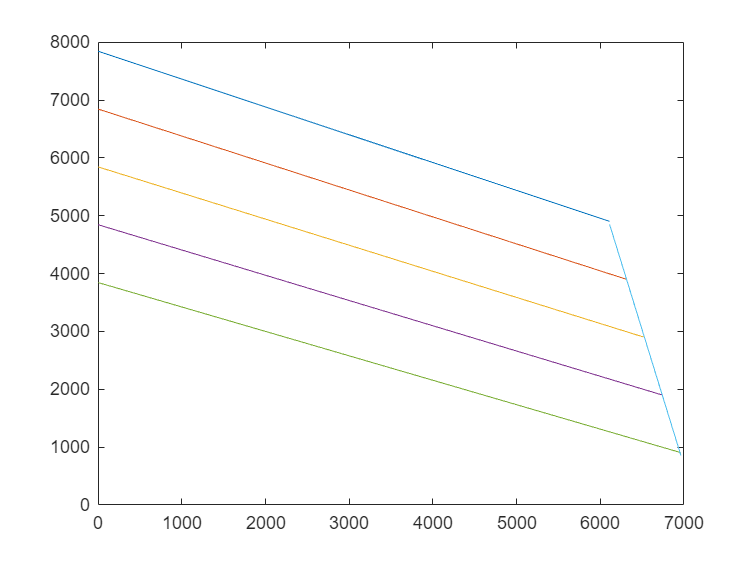

figure
plot(E1,Wpay_1)
hold on
plot(E2,Wpay_2)
hold on
plot(E3,Wpay_3)
hold on
plot(E4,Wpay_4)
hold on
plot(E5,Wpay_5)
hold on
plot(maxendurance,minpay_fit_E)
hold off

%%%%%% Autorotation (rate of  decent) 

